## *一维输出*

K = 2; M = 16;
Rc = 1*15;
Rc_list = 1*15:1*15:2*15;

theta = -90:2:90;
phi = 0:10:180;
target_theta = -90:2:90;
target_phi = 0:20:180;

u_ = sind(theta).' * cosd(phi);
v_ = sind(theta).' * sind(phi);
angles_uv = [u_(:), v_(:)];

u_ = sind(target_theta).' * cosd(target_phi);
v_ = sind(target_theta).' * sind(target_phi);
target_uv = [u_(:), v_(:)];

[lia, sample] = ismember(target_uv, angles_uv, 'rows');
f = 1;
 
valratio = 0.2;
N_elements = 16;

% MLP数据，角度作为输出
dataFolder = 'planar_cp_dataset/';  % 你的数据目录
fileList = dir(fullfile(dataFolder, '*.mat'));

X_set = [];
Y_set = [];

% Y : sample*C*theta*phi
k = 1;
% 
for Rc_train = Rc_list
    for i = 1:450
        filename = sprintf( dataFolder + "Gn_%d", i);
        load(filename + ".mat");
    
        points = model_points{1};
    
        ln_all = zeros(K*M + 2, N_elements);
        for j = 1:16
            ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc_train, 15, [Inf,Inf], 22.5, 22.5);
        end
        X_set = [X_set; ln_all.'];
        % ln = calculate_ABE_features_planar(model_points{1}, 4*15, 0.25*15);
        % X_set = [X_set; ln];
    
        Gn_theta = G_complex_all(sample, 1, f, :);
        Gn_phi = G_complex_all(sample, 2, f, :);
        % Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
        Gn = Gn_theta;
        Gn = reshape(Gn, [size(sample, 1) N_elements]);
        Y_set = [Y_set; Gn.'];
    %     Y_set(k,:,:,:) = ;
    end
end

Y_set = [real(Y_set), imag(Y_set)];
XTrain = X_set();
YTrain = Y_set();


X_set = [];
Y_set = [];
for i = 451:500
    filename = sprintf( dataFolder + "Gn_%d", i);
    load(filename + ".mat");

    points = model_points{1};

    ln_all = zeros(K*M + 2, N_elements);
    for j = 1:16
        ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 22.5, 22.5);
    end
    X_set = [X_set; ln_all.'];
    % ln = calculate_ABE_features_planar(model_points{1}, 4*15, 0.25*15);
    % X_set = [X_set; ln];

    Gn_theta = G_complex_all(sample, 1, f, :);
    Gn_phi = G_complex_all(sample, 2, f, :);
    % Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
    Gn = Gn_theta;
    Gn = reshape(Gn, [size(sample, 1) N_elements]);
    Y_set = [Y_set; Gn.'];
%     Y_set(k,:,:,:) = ;
end

Y_set = [real(Y_set), imag(Y_set)];
XValidation = X_set();
YValidation = Y_set();

cv = cvpartition(size(X_set, 1), 'HoldOut', 0.1);  

% 获取训练和测试索引
idxTrain = training(cv);
idxTest = test(cv);

% 提取训练集和测试集
% XTrain = X_set(idxTrain, :,:);
% YTrain = Y_set(idxTrain, :,:);

% XValidation = X_set(idxTest, :,:);
% YValidation = Y_set(idxTest, :,:);

save('python_file\dataset.mat','XTrain',"YTrain","YValidation","XValidation");

二维输出 - 【theta, phi】

% input = 1D; output = 2D(theta, phi)
K = 2; M = 16;
Rc = 1*15;
Rc_list = 1*15:1*15:2*15;

theta = -90:2:90;
phi = 10:10:180;
target_theta = -90:2:90;
target_phi = 0:20:180;
[~, theta_indices] = ismember(target_theta, theta);
[~, phi_indices] = ismember(target_phi, phi);

f = 1;
 
valratio = 0.2;
N_elements = 16;

% MLP数据，角度作为输出
dataFolder = 'planar_cp_dataset/';  % 你的数据目录
fileList = dir(fullfile(dataFolder, '*.mat'));

X_set = [];
Y_set = [];

% Y : sample*C*theta*phi
k = 1;
% 
for Rc_train = Rc_list
    for i = 1:350
        filename = sprintf( dataFolder + "Gn_%d", i);
        load(filename + ".mat");
    
        points = model_points{1};
    
        ln_all = zeros(K*M + 2, N_elements);
        for j = 1:16
            ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc_train, 15, [Inf,Inf], 22.5, 22.5);
        end
        X_set = [X_set; ln_all.'];
        % ln = calculate_ABE_features_planar(model_points{1}, 4*15, 0.25*15);
        % X_set = [X_set; ln];
    
        Gn_theta = G_complex_all(:, 1, f, :);
        Gn_phi = G_complex_all(:, 2, f, :);
        % Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
        Gn = Gn_theta;
        Gn = reshape(Gn, [1729 N_elements]);
        %         Y_set = [Y_set; Gn.'];
        Gn = reshape(Gn, [size(theta,2) 19 16]);
        Gn = Gn(theta_indices, phi_indices, :);
        order = [3,1,2];
        Gn = permute(Gn, order);
        Y_set = [Y_set; Gn];
    end
end

Y_set = [real(Y_set)];
Y_set = reshape(Y_set, size(Y_set, 1), size(Y_set, 2), []);
XTrain = X_set();
YTrain = Y_set();


X_set = [];
Y_set = [];
for i = 351:390
    filename = sprintf( dataFolder + "Gn_%d", i);
    load(filename + ".mat");

    points = model_points{1};

    ln_all = zeros(K*M + 2, N_elements);
    for j = 1:16
        ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 22.5, 22.5);
    end
    X_set = [X_set; ln_all.'];
    % ln = calculate_ABE_features_planar(model_points{1}, 4*15, 0.25*15);
    % X_set = [X_set; ln];
    
    Gn_theta = G_complex_all(:, 1, f, :);
    Gn_phi = G_complex_all(:, 2, f, :);
    % Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
    Gn = Gn_theta;
    Gn = reshape(Gn, [1729 N_elements]);
    %         Y_set = [Y_set; Gn.'];
    Gn = reshape(Gn, [size(theta,2) 19 16]);
    Gn = Gn(theta_indices, phi_indices, :);
    order = [3,1,2];
    Gn = permute(Gn, order);
    Y_set = [Y_set; Gn];
end

Y_set = [real(Y_set)];
Y_set = reshape(Y_set, size(Y_set, 1), size(Y_set, 2), []);
XValidation = X_set();
YValidation = Y_set();

cv = cvpartition(size(X_set, 1), 'HoldOut', 0.1);  

% 获取训练和测试索引
idxTrain = training(cv);
idxTest = test(cv);

% 提取训练集和测试集
% XTrain = X_set(idxTrain, :,:);
% YTrain = Y_set(idxTrain, :,:);

% XValidation = X_set(idxTest, :,:);
% YValidation = Y_set(idxTest, :,:);

save('python_file\dataset.mat','XTrain',"YTrain","YValidation","XValidation");

二维输出 - 【u，v】

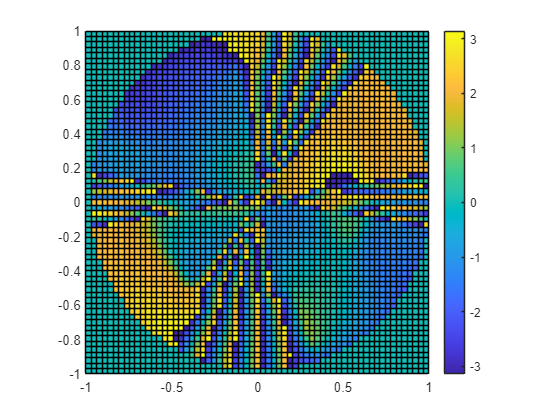

% input = 1D; output = 2D(theta, phi)
K = 2; M = 16;
Rc = 1*15;
Rc_list = 1*15:1*15:1*15;

theta = -90:2:90;
phi = 0:10:180;
f = 1;
u = sind(theta).' * cosd(phi);
v = sind(theta).' * sind(phi);
u = u(:); v = v(:);

nGridPoints = 64; % 网格精细度，例如 201x201
u_grid_vec = linspace(-1, 1, nGridPoints);
v_grid_vec = linspace(-1, 1, nGridPoints);
[U_grid, V_grid] = meshgrid(u_grid_vec, v_grid_vec);
 
valratio = 0.2;
N_elements = 16;


% MLP数据，角度作为输出
dataFolder = 'planar_cp_dataset/';  % 你的数据目录

outC = 4;          % 目标图像通道数
outH = 64;         % 目标图像高度
outW = 64;         % 目标图像宽度

X_set = [];
Y_set = zeros(1, outC, outH, outW);
Gn = [];
G_ = zeros(4, 64, 64);

% Y : sample*C*theta*phi
k = 1;
% 
for Rc_train = Rc_list
    for i = 1
        filename = sprintf( dataFolder + "Gn_%d", i);
        load(filename + ".mat");
    
        points = model_points{1};
    
        ln_all = zeros(K*M + 2, N_elements);
        for j = 1:16
            ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc_train, 15, [Inf,Inf], 22.5, 22.5);
        end
        X_set = [X_set; ln_all.'];
        % ln = calculate_ABE_features_planar(model_points{1}, 4*15, 0.25*15);
        % X_set = [X_set; ln];

        Gn_theta = G_complex_all(:, 1, f, :);
        Gn_phi = G_complex_all(:, 2, f, :);
        Gn_rh = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
        Gn_lh = 1/sqrt(2)*(Gn_theta + 1j*Gn_phi);
        Gn = [];
        Gn(:,1,:,:) = abs(Gn_rh);
        Gn(:,2,:,:) = unwrap(angle(Gn_rh));
        Gn(:,3,:,:) = abs(Gn_lh);
        Gn(:,4,:,:) = unwrap(angle(Gn_lh));

        order = [3,2,1];
        Gn = permute(Gn, order); % [16 4 sample]
        for j = 1:N_elements
            for c = 1:4
                temp = Gn(j,c,:);
                temp = squeeze(temp);
                G_(c,:,:) = griddata(u, v, temp, U_grid, V_grid, 'natural'); % 'natural' 是常用的插值方法
                idx_NAN = isnan(G_);
                G_(idx_NAN) = 0;
            end
            Y_set(k, :, :, :) = G_;
            k = k+1;
        end
    end
end

XTrain = X_set();
YTrain = Y_set();

X_set = [];
Y_set = [];

k=1;
for i = 351
    filename = sprintf( dataFolder + "Gn_%d", i);
    load(filename + ".mat");

    points = model_points{1};

    ln_all = zeros(K*M + 2, N_elements);
    for j = 1:16
        ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc_train, 15, [Inf,Inf], 22.5, 22.5);
    end
    X_set = [X_set; ln_all.'];
    % ln = calculate_ABE_features_planar(model_points{1}, 4*15, 0.25*15);
    % X_set = [X_set; ln];

    Gn_theta = G_complex_all(:, 1, f, :);
    Gn_phi = G_complex_all(:, 2, f, :);
    Gn_rh = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
    Gn_lh = 1/sqrt(2)*(Gn_theta + 1j*Gn_phi);
    Gn = [];
    Gn(:,1,:,:) = abs(Gn_rh);
    Gn(:,2,:,:) = unwrap(angle(Gn_rh));
    Gn(:,3,:,:) = abs(Gn_lh);
    Gn(:,4,:,:) = unwrap(angle(Gn_lh));

    order = [3,2,1];
    Gn = permute(Gn, order); % [16 4 sample]
    for j = 1:N_elements
        for c = 1:4
            temp = Gn(j,c,:);
            temp = squeeze(temp);
            G_(c,:,:) = griddata(u, v, temp, U_grid, V_grid, 'natural'); % 'natural' 是常用的插值方法
            idx_NAN = isnan(G_);
            G_(idx_NAN) = 0;
        end
        Y_set(k, :, :, :) = G_;
        k = k+1;
    end
end

XValidation = X_set();
YValidation = Y_set();


save('python_file\dataset.mat','XTrain',"YTrain","YValidation","XValidation");

二维方向图合成

c = 4;
i = 6;

temp = YValidation(i,c,:,:);
temp = wrapToPi(squeeze(temp));
figure;
pcolor(U_grid, V_grid, temp);

axis equal;
colorbar;
axis([-1 1 -1 1]);
% figure;
% pcolor(U_grid, V_grid, YPred(:,:,:,i));
% shading interp; % 平滑颜色过渡，隐藏网格线
% axis equal;
% colorbar;
% axis([-1 1 -1 1]);


load(dataFolder + "Gn_451.mat");
load('python_file\preds.mat');
real_ = 1:91;imag_ = 92:182;
pred_theta_complex = preds(:, real_) + 1j*preds(:, imag_);
Gn_theta = G_complex_all(:, 1, f, :);
Gn_phi = G_complex_all(:, 2, f, :);
% Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
Gn = Gn_theta;
Gn = reshape(Gn, [1729 N_elements]);
%         Y_set = [Y_set; Gn.'];
Gn = reshape(Gn, [size(theta,2) 19 16]);
Gn = Gn(theta_indices, phi_indices, :);
order = [3,1,2];
Gn = permute(Gn, order);

i=2;
p = 1;
figure;hold on;box on;
plot(target_theta, real(Gn(i, :, p)));
plot(target_theta, real(pred_theta_complex(i, :, p)));
xlabel('theta');
ylabel('rE');
legend('sim', 'pred', 'box', 'off');
title(sprintf('phi = %d', (p-1)*20));
figure;hold on;box on;
plot(target_theta, imag(Gn(i, :, p)));
plot(target_theta, imag(pred_theta_complex(i, :, p)));
xlabel('theta');
ylabel('rE');
legend('sim', 'pred', 'box', 'off');
title(sprintf('phi = %d', (p-1)*20));

load(dataFolder + "Gn_451.mat");
load('python_file\preds.mat');
real_ = 1:91;imag_ = 92:182;
pred_theta_complex = preds(:, real_) + 1j*preds(:, imag_);
Gn_theta = G_complex_all(:, 1, f, :);
Gn_phi = G_complex_all(:, 2, f, :);
% Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
Gn = Gn_theta;
Gn = reshape(Gn, [1729 N_elements]);
%         Y_set = [Y_set; Gn.'];
Gn = reshape(Gn, [size(theta,2) 19 16]);
Gn = Gn(theta_indices, phi_indices, :);
order = [3,1,2];
Gn = permute(Gn, order);

p = 1;
figure;hold on;box on;
plot(target_theta, real(Gn(i, :, p)));
plot(target_theta, real(pred_theta_complex(i, :, p)));
xlabel('theta');
ylabel('rE');
legend('sim', 'pred', 'box', 'off');
title(sprintf('phi = %d', (p-1)*20));
figure;hold on;box on;
plot(target_theta, imag(Gn(i, :, p)));
plot(target_theta, imag(pred_theta_complex(i, :, p)));
xlabel('theta');
ylabel('rE');
legend('sim', 'pred', 'box', 'off');
title(sprintf('phi = %d', (p-1)*20));


theta = -90:2:90;
phi = 0:10:180;
target_theta = -90:4:90;
target_phi = 0:20:180;
[~, theta_indices] = ismember(target_theta, theta);
[~, phi_indices] = ismember(target_phi, phi);

Gn_theta = G_complex_all(:, 1, f, :);
Gn_phi = G_complex_all(:, 2, f, :);
% Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
Gn = Gn_theta;
Gn = reshape(Gn, [1729 N_elements]);
%         Y_set = [Y_set; Gn.'];
Gn = reshape(Gn, [size(theta,2) size(phi,2) 16]);
Gn = Gn(theta_indices, phi_indices);
order = [3,1,2];
Gn = permute(Gn, order);

i = 1;
phi = 4;
real_ = 1:91;imag_ = 92:182;
Y_complex = YValidation(i, real_, :) + 1j*YValidation(i, imag_, :);


Gn_theta = G_complex_all(:, 1, f, :);
Gn_phi = G_complex_all(:, 2, f, :);
% Gn = 1/sqrt(2) * (Gn_theta - 1j*Gn_phi);
Gn = Gn_theta;
Gn = reshape(Gn, [1729 N_elements]);
%         Y_set = [Y_set; Gn.'];
Gn = reshape(Gn, [size(theta,2) 19 16]);
Gn = Gn(theta_indices, phi_indices, :);
order = [3,1,2];
Gn = permute(Gn, order);
plot(real(Gn(i, :, phi)));
% Gn = reshape(Gn, [size(target_theta,2) size(target_phi,2) 16]);
% order = [3,1,2];
% Gn = permute(Gn, order);
% plot(abs(Gn(i, :, phi)));
